[audio, fs] = audioread('samples/syllables/TURMER/common_blackbird_long_1.wav');

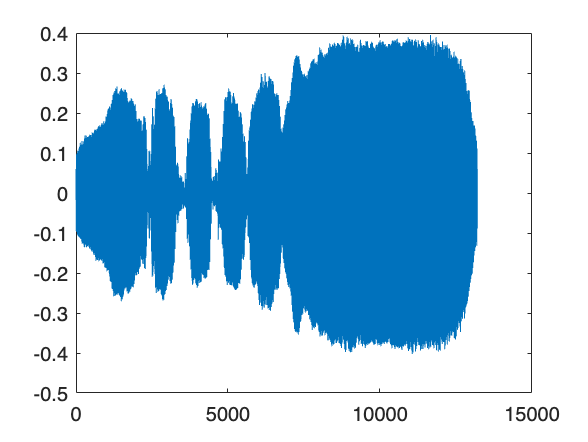

plot(audio)

gammaFiltBank = gammatoneFilterBank([50 20000],64,fs);

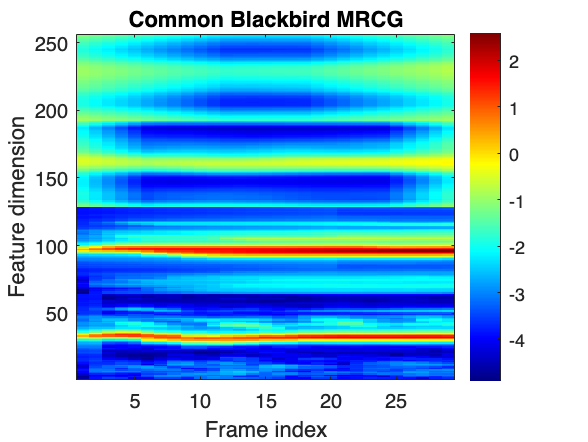

audioOut = gammaFiltBank(audio);
mrcgFeatures = mrcg(audioOut, fs);
imagesc(mrcgFeatures);
colormap jet
colorbar
ylabel('Feature dimension')
xlabel('Frame index')
title('Common Blackbird MRCG')
set(gca,'YDir','normal')

frameSizeMs = 20;
frameSize = floor((frameSizeMs/1000)*fs);
overlapSize = frameSize/2;
[numSamples, numChannels] = size(audioOut);
numFrames = floor((numSamples-frameSize)/overlapSize+1)+1;
frames = zeros(numChannels,frameSize,numFrames);
for ii = 1:numChannels
    frames(ii,:,:) = buffer(audioOut(:,ii),frameSize,frameSize-overlapSize,'nodelay');
end

cochleagram = squeeze(sum(frames.^2,2));

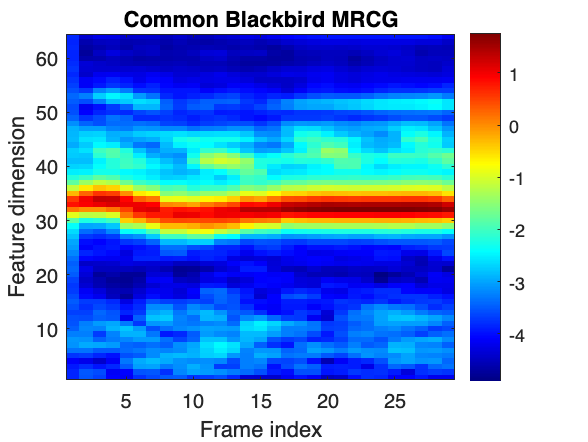

imagesc(log10(cochleagram));
colormap jet
colorbar
ylabel('Feature dimension')
xlabel('Frame index')
title('Common Blackbird MRCG')
set(gca,'YDir','normal')

frameSizeMs = 200;
frameSize = floor((frameSizeMs/1000)*fs);
overlapSize = floor((10/1000)*fs);
[numSamples, numChannels] = size(audioOut);
numFrames = floor((numSamples-frameSize)/overlapSize+1)+1;
frames = zeros(numChannels,frameSize,numFrames);
for ii = 1:numChannels
    frames(ii,:,:) = buffer(audioOut(:,ii),frameSize,frameSize-overlapSize);
end

Unable to perform assignment because the size of the left side is 1-by-8820-by-11 and the size of the right side is 8820-by-30.

cochleagram = squeeze(sum(frames.^2,2));

imagesc(log10(cochleagram));
colormap jet
colorbar
ylabel('Feature dimension')
xlabel('Frame index')
title('Common Blackbird MRCG')
set(gca,'YDir','normal')